# 仿真数据后处理

clear
% 导入仿真结果数据
load("Sim_result.mat")

t=out.Time;
x_g=out.Data(:,1);
y_g=out.Data(:,2);
psi=out.Data(:,3);
beta=out.Data(:,4);
vx=out.Data(:,5);
vy=out.Data(:,6);
phi_r=out.Data(:,7);
delta_f=out.Data(:,8);

Fx_f=2.*out.Data(:,9);
Fx_r=2.*out.Data(:,10);


% 导入参考数据
load("reference_processed.mat")



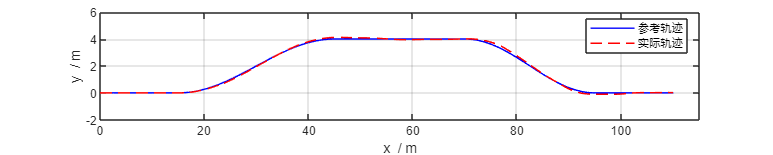


% 轨迹及轨迹误差
figure(Units="centimeters",Position=[5,5,40,8])
hold on
plot(x_ref,y_ref,'-b',LineWidth=1)
plot(x_g,y_g,'--r',LineWidth=1)
hold off
box on
grid on
legend('参考轨迹','实际轨迹')
xlim([0,115])
ylim([-2,6])
xlabel('x  / m')
ylabel('y  / m')

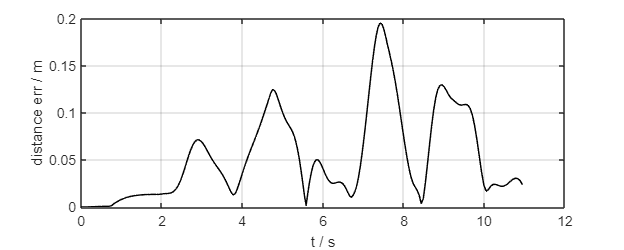


% 轨迹误差

% 重新插值对齐
y_g1=interp1(t,y_g,t_ref,'linear','extrap'); 
x_g1=interp1(t,x_g,t_ref,'linear','extrap');
psi1=interp1(t,psi,t_ref,'linear','extrap');

figure(Units="centimeters",Position=[5,5,15,6])
plot(t_ref,sqrt((y_g1-y_ref).^2+(x_g1-x_ref).^2),'-k',LineWidth=1)
box on
grid on
xlabel('t / s')
ylabel('distance err / m')

disp(['轨迹跟踪平均误差：',num2str(sum(sqrt((y_g1-y_ref).^2+(x_g1-x_ref).^2))/length(y_ref)),' m'])

轨迹跟踪平均误差：0.055411 m


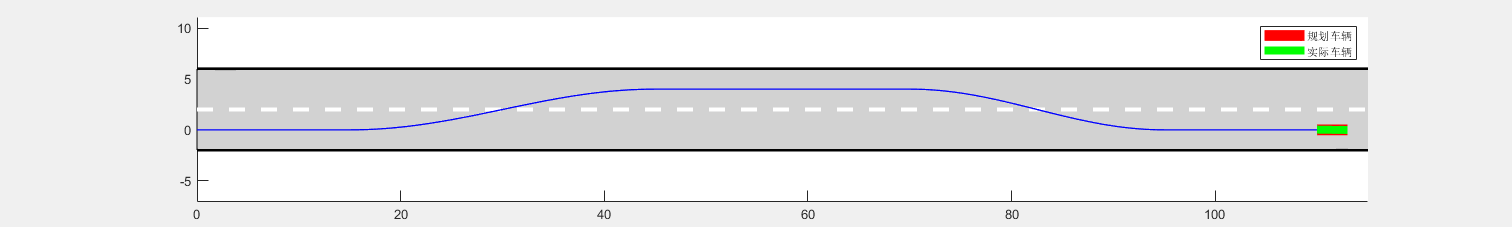

% 动画展示
L=3; % 轴距（近似车长）

road_len=115;

v = VideoWriter("result.avi");
open(v)

h=figure(Units="centimeters",Position=[5,5,40,6]);
hold on

% 画车道
rectangle(Position=[0,-2,150,8],FaceColor=[211 211 211]./256)
plot([0,road_len],[2,2],'w--',LineWidth=3)
plot([0,road_len],[-2,-2],'k-',LineWidth=2)
plot([0,road_len],[6,6],'k-',LineWidth=2)
% 画参考轨迹
plot(x_ref,y_ref,'-b',LineWidth=1)

xlim([0,road_len])
ylim([-3,7])
axis equal

h.Visible = 'off';
for i=1:length(t_ref)
    if i > 1
        delete(h1); % 清除前一个曲线
        delete(h2); % 清除前一个曲线
    end

    h1=plot([x_ref(i),x_g1(i)+L*cos(phi_ref(i))],[y_ref(i),y_ref(i)+L*sin(phi_ref(i))],'-r',LineWidth=8);
    h2=plot([x_g1(i),x_g1(i)+L*cos(psi1(i))],[y_g1(i),y_g1(i)+L*sin(psi1(i))],'-g',LineWidth=6);
    
    legend([h1,h2],{'规划车辆','实际车辆'})

    drawnow; % 更新图形
    M(i) = getframe;
    writeVideo(v,M(i))

end
hold off
h.Visible = 'on';

close(v)

movie(M,1,5); % (帧结构数组，播放次数，播放帧率）

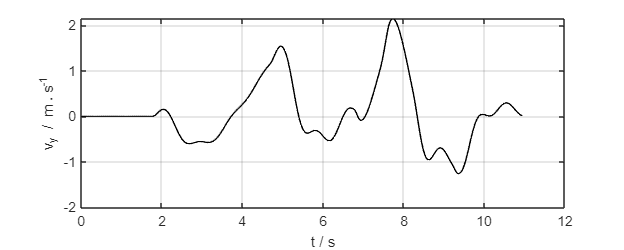

% 车辆状态：横向车速、质心侧偏角、横摆角速度

% 横向车速
figure(Units="centimeters",Position=[5,5,15,6])
plot(t,vy,'-k',LineWidth=1)
box on
grid on
xlabel('t / s')
ylabel('v_y / m\cdots^{-1}')

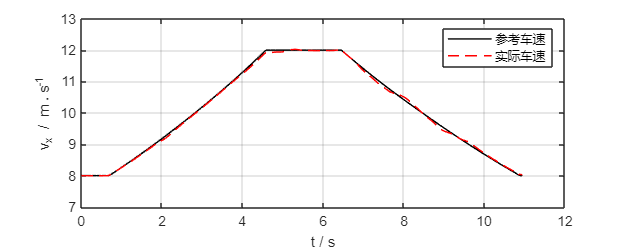

% 纵向车速
figure(Units="centimeters",Position=[5,5,15,6])
hold on
plot(t_ref,v_ref,'-k',LineWidth=1)
plot(t,vx,'--r',LineWidth=1)
hold off
box on
grid on
legend('参考车速','实际车速')
xlabel('t / s')
ylabel('v_x / m\cdots^{-1}')

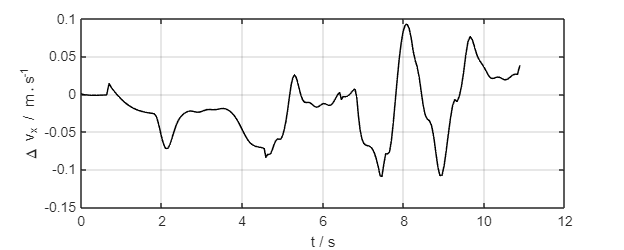

% 纵向车速
figure(Units="centimeters",Position=[5,5,15,6])
hold on
v_real=interp1(t,vx,t_ref);
plot(t_ref,v_real-v_ref,'-k',LineWidth=1)

hold off
box on
grid on

xlabel('t / s')
ylabel('\Delta v_x / m\cdots^{-1}')

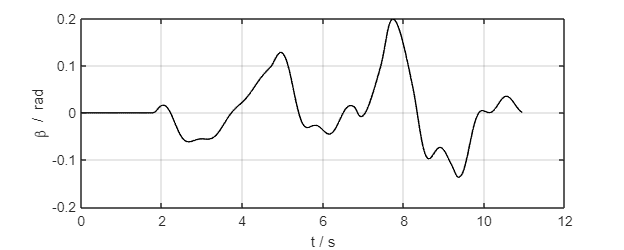



% 质心侧偏角
figure(Units="centimeters",Position=[5,5,15,6])
plot(t,beta,'-k',LineWidth=1)
box on
grid on
xlabel('t / s')
ylabel('\beta / rad')

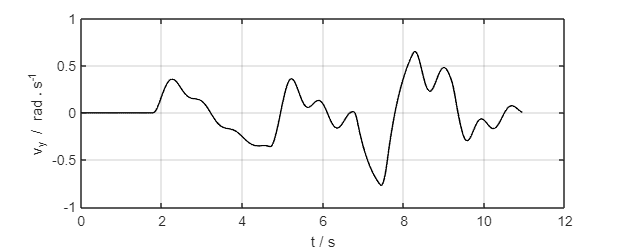


% 横摆角速度
figure(Units="centimeters",Position=[5,5,15,6])
plot(t,phi_r,'-k',LineWidth=1)
box on
grid on
xlabel('t / s')
ylabel('v_y / rad\cdots^{-1}')

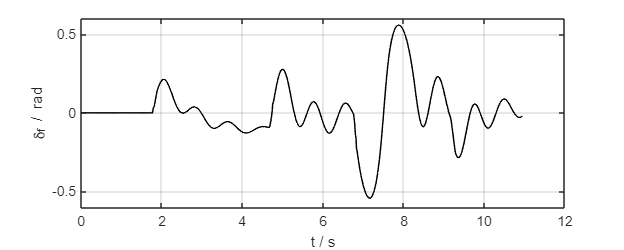

% 前轮转角输入
figure(Units="centimeters",Position=[5,5,15,6])
plot(t,delta_f,'-k',LineWidth=1)
box on
grid on
xlabel('t / s')
ylabel('\delta_f / rad')

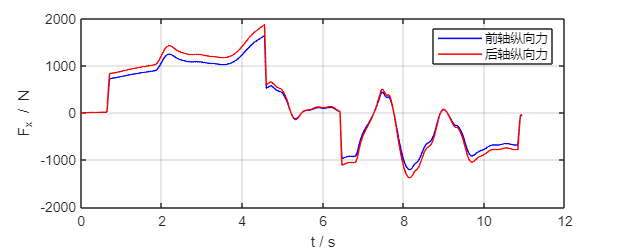


% 前后轮的驱动转矩
figure(Units="centimeters",Position=[5,5,15,6])
hold on
plot(t,Fx_f,'-b',LineWidth=1)
plot(t,Fx_r,'-r',LineWidth=1)
hold off
box on
grid on
legend('前轴纵向力','后轴纵向力')
xlabel('t / s')
ylabel('F_x / N')